## Analysis of fixed points and stability of the linear difference equation model for social mobilization. 

The model is described in detail in chapter 2 of Huckfeldt, Kohefld, Likens (1982).

∆M = g(L - Mt)– fMt

- where g is the probability (or rate) of gaining members within time step

- f is the probability (or rate) of loosing members within time step

- L is the proportion of people in the population that are “mobilizable”

Standard form:

Mt+1 = (1-g-f)*Mt + gL

## Fixed points:

% Define symbolic function f(x) and symbolic variable x
syms f(x) g f L s

f(x) = (1-g-f)*x+g*L; 

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the symbolic expression for the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x);
fp

$$fp = \frac{L\,g}{f+g}$$

The model has a single fixed point as expected for a linear model.

## Stability analysis:

Standard form for a first-order difference equation is : Mt+1 = a0 + a1*Mt.

Our model in standard form: Mt+1 = (1-g-f)*Mt + gL ,where **a****0****= ****gL**and **a****1****= (1-g-f)**

syms f(x) g f L s
g_in = 0.16;
f_in = 0.34;
L_in = 1;

% substitute specific values of g, f, and L parameters into the model
f(x) = subs((1-g-f)*x+g*L,{g,f,L},[g_in,f_in,L_in]);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the symbolic expression for the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);
fp_num

fp_num = 0.3200


% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = 0.5000


% Classify fixed points
stable_fp = abs(m_num)<1;
unstable_fp = abs(m_num)>1;

% Plot the function and the fixed points
figure
fplot(f(x),[0 1])
hold

Current plot held


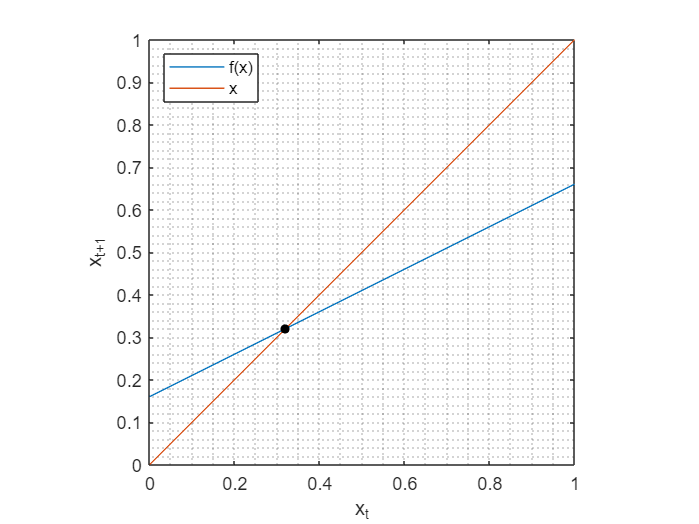

fplot(x,[0 1])

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points
grid minor
axis square
ylabel('x_{t+1}')
xlabel('x_t')
legend('f(x)','x','Location','Northwest')

## Numerical simulation of the model

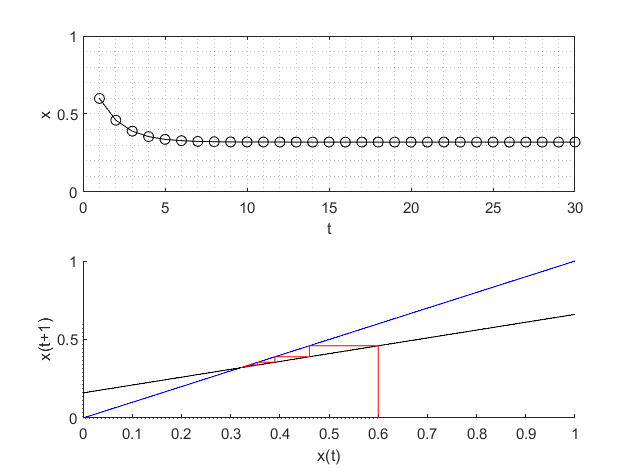

[xt] = LinearSocialMobilization(0.6, g_in, f_in, L_in, 30, .25);

## Project idea: Application to real-data

Apply this model to one of the poll data time series from [https://fivethirtyeight.com/.](https://fivethirtyeight.com) For example, Joe Biden's approval rating from the first day in office: [https://projects.fivethirtyeight.com/biden-approval-rating/.](https://projects.fivethirtyeight.com/biden-approval-rating) I downloaded the data for the approval rating and selected only the Monmouth University survey results - these are done monthly and have very high quality rating. 

Let's load the data (full data could be [downloaded here](https://github.com/Nikita868/PSYC9015-Dynamics/blob/8cdd9dd675030676fb32f537f589d113a711a053/Topic%202%20Difference%20Equations/approval_polllist.xlsx)).

load('MonmouthPollBiden.mat')

Plot the poll results:

figure
plot(poll,'.-')
xlabel('Months in office')
ylabel('Approval rating')
ylim([0,1])

Plot the month vs. month+1 approval ratings:

figure
plot(poll(1:end-1),poll(2:end),'.')
grid on
xlim([0,1])
ylim([0,1])
ylabel('Approval t+1')
ylabel('Approval t')

Estimate the model parameters using these data. Fit linear model to Approval t vs. Approval t+1 and get the intercept (m0) and slope (m1)

mdl = fitlm(poll(1:end-1),poll(2:end))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    0.030128    0.10107    0.29808      0.77569
    x1               0.8979    0.21006     4.2744    0.0052376


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.0286
R-squared: 0.753,  Adjusted R-Squared: 0.712
F-statistic vs. constant model: 18.3, p-value = 0.00524

m0 = mdl.Coefficients.Estimate(1)

m0 = 0.0301

m1 = mdl.Coefficients.Estimate(2)

m1 = 0.8979

Find the estimates for model parameters, assuming that L = 0.7 (mobilizable proportion in population to support Biden): See slide 70 in the class materials to understand where the formulas for the parameter estimates come from:

L = 0.7

L = 0.7000

g = m0/L

g = 0.0430

f = 1-g-m1

f = 0.0591

Let's run the model with the estimated parameters:

x_in = poll(1)

x_in = 0.5400

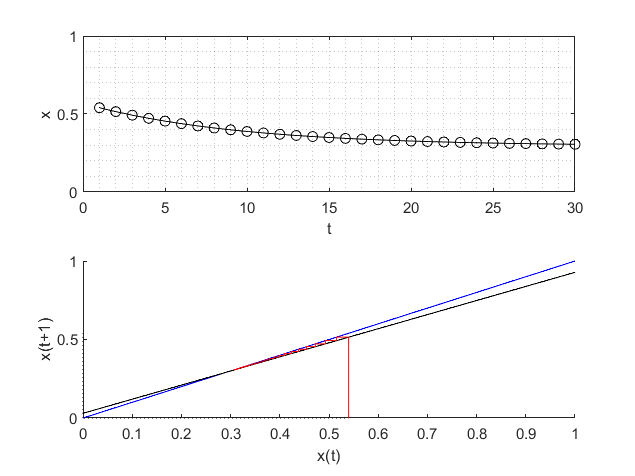

[xt] = LinearSocialMobilization(0.54, g, f, L, 30, .25);


fixed_point = L*(g/(g+f))

fixed_point = 0.2951


% model vs. data
figure
plot(xt)
hold

Current plot held


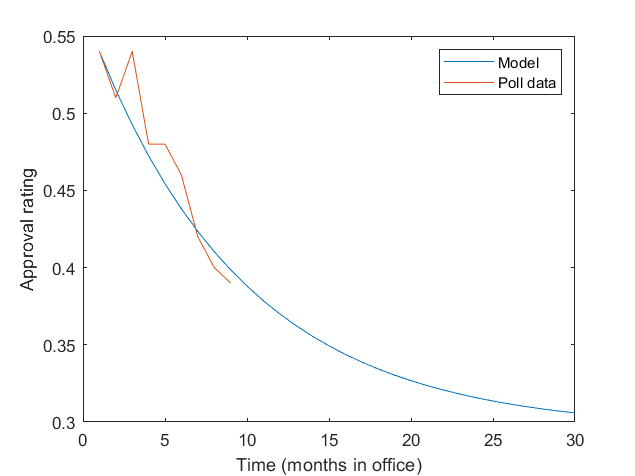

plot(poll)
ylabel('Approval rating')
xlabel('Time (months in office)')
legend('Model','Poll data','Location','Northeast')